clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

%-----------------------------
% 产生信号
source;
tag;
global y_sig;
y_sig = y_source .* y_tag;

% dB 单位信噪比
y_noise = awgn(y_sig, 50);
y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点

N_inside = 50;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);

% 计算三个距离
[d1, d2, d3] = xy2d(x, y);

single_run(d1, d2, d3, false, 'inside');

delta t is
   1.0e-07 *

  列 1 至 16

    0.0932    0.0355    0.1216    0.0227    0.0586    0.1971    0.0768    0.0571    0.0714    0.0228    0.0768    0.0414    0.1671    0.0344    0.1104    0.1355

  列 17 至 32

    0.0622    0.1215    0.1620    0.1587    0.1287    0.0711    0.1907    0.0562    0.1302    0.2109    0.0834    0.1970    0.0201    0.0886    0.0737    0.1628

  列 33 至 48

    0.1865    0.1802    0.0720    0.1155    0.1701    0.2022    0.0660    0.1330    0.0802    0.1651    0.1504    0.0523    0.1381    0.0333    0.2204    0.1546

  列 49 至 50

    0.1361    0.0288



## 房间外的随机点

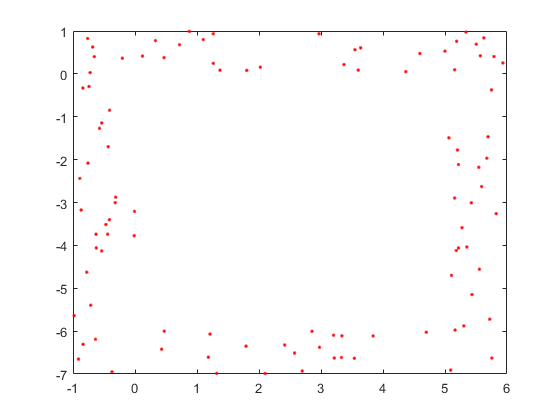

% 1/4 的数量
N_outside = 25;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
% TODO: bugfix --- 点都集中在四个角落了，需要分散到边边上
figure; plot(x0,y0,'r.');


% 计算三个距离
[d1_0, d2_0, d3_0] = xy2d(x0, y0);
SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside');

delta t is
   1.0e-07 *

  列 1 至 16

    0.0301    0.0246    0.0340    0.0301    0.0319    0.0639    0.0558    0.0852    0.0386    0.0790    0.0316    0.0408    0.0323    0.0603    0.2003    0.0303
    0.1427    0.1984    0.1573    0.2191    0.1427    0.2479    0.2529    0.2656    0.2375    0.1968    0.1463    0.1072    0.3314    0.3295    0.2814    0.3518
    0.4493    0.4172    0.4664    0.4840    0.4041    0.4387    0.4485    0.4262    0.4468    0.4744    0.4317    0.4136    0.2822    0.2084    0.2575    0.2563
    0.4873    0.4666    0.4614    0.4904    0.4840    0.5505    0.4617    0.4901    0.4357    0.4533    0.4492    0.4821    0.5570    0.5000    0.3899    0.4396

  列 17 至 25

    0.0483    0.0803    0.1546    0.0974    0.0366    0.1781    0.0638    0.1048    0.1280
    0.2437    0.2768    0.2988    0.3125    0.2249    0.3432    0.2294    0.3128    0.2819
    0.2574    0.2419    0.2344    0.3159    0.3834    0.3657    0.2208    0.2236    0.2780
    0.4996    0.5065    0.3804  



% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end